%Extracting the Actual Movement Each Time
clf
clear all;
path = "D:\Senior LAb\Model_testplus_Rev_03.csv"

path = "D:\Senior LAb\Model_testplus_Rev_03.csv"

dataTable = readtable(path)

dataTable = 1000000×2 table
    Time_s_    Channel1_V_
    _______    ___________

         -5     -0.018182 
         -5     -0.018182 
         -5     -0.018182 
         -5     -0.018182 
         -5     -0.018182 
    -4.9999     -0.018182 
    -4.9999     -0.018182 
    -4.9999     -0.018182 
    -4.9999     -0.014451 
    -4.9999     -0.018182 
    -4.9999     -0.018182 
    -4.9999     -0.018182 
    -4.9999     -0.014451 
    -4.9999     -0.014451 
    -4.9999     -0.014451 
    -4.9998     -0.014451 


dataArray = table2array(dataTable)

dataArray =    -5.0000   -0.0182
   -5.0000   -0.0182
   -5.0000   -0.0182
   -5.0000   -0.0182
   -5.0000   -0.0182
   -4.9999   -0.0182
   -4.9999   -0.0182
   -4.9999   -0.0182
   -4.9999   -0.0145
   -4.9999   -0.0182


backing = zeros(1,1)

backing = 0

forwarding = zeros(1,1)

forwarding = 0

R = 700

R = 700

%ลูกแรก
time_1_b = 0:1e-5:(360585-322719)*1e-5;
time_1_f = 0:1e-5:(419965-378657)*1e-5;
backing_1 = dataArray(322719:360585,2);
forwarding_1 = dataArray(378657:419965,2);
b_flip_01 = abs(backing_1)

b_flip_01 =     0.0145
    0.0145
    0.0145
    0.0145
    0.0145
    0.0145
    0.0145
    0.0145
    0.0145
    0.0145


f_flip_01 = abs(forwarding_1)

f_flip_01 =     0.0145
    0.0145
    0.0182
    0.0182
    0.0145
    0.0145
    0.0145
    0.0182
    0.0107
    0.0145



b_power_01 = b_flip_01.^2/R

b_power_01 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


f_power_01 = f_flip_01.^2/R

f_power_01 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


en_b01 = 0

en_b01 = 0

en_f01 = 0

en_f01 = 0

for j=1:length(b_power_01)-1
    en_b01 = en_b01 + (b_power_01(j+1)+b_power_01(j))*(time_1_b(j+1)-time_1_b(j))/2;
end
for j=1:length(f_power_01)-1
    en_f01 = en_f01 + (f_power_01(j+1)+f_power_01(j))*(time_1_f(j+1)-time_1_f(j))/2;
end
en_b01

en_b01 = 1.4183e-05

en_f01

en_f01 = 5.9445e-05

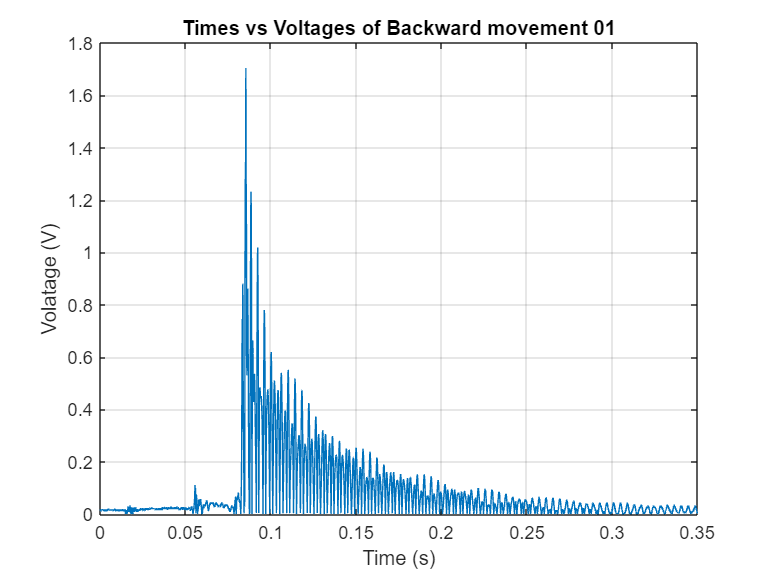


figure()
plot(time_1_b,b_flip_01)
xlim([0 0.35])
title("Times vs Voltages of Backward movement 01")
xlabel("Time (s)")
ylabel("Volatage (V)")
grid on
saveas(gcf,"backward movement.png")

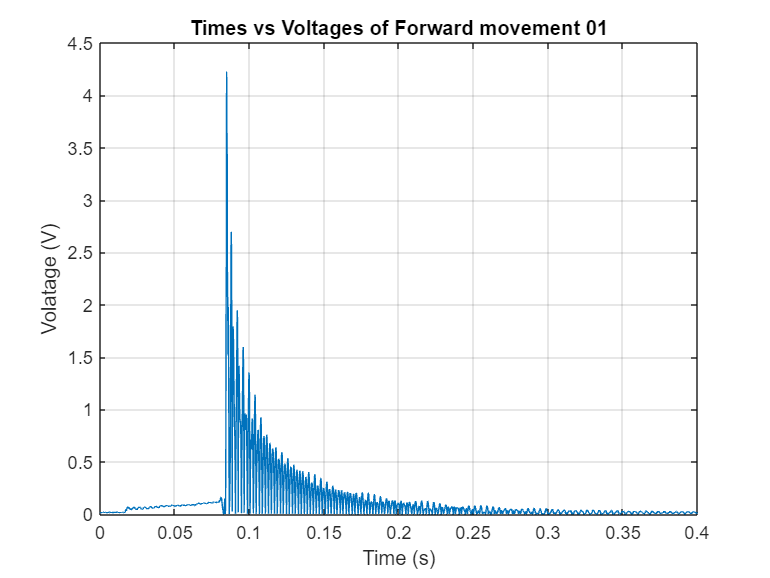

figure()
plot(time_1_f,f_flip_01)
title("Times vs Voltages of Forward movement 01")
xlabel("Time (s)")
ylabel("Volatage (V)")
grid on
saveas(gcf,"forward movement.png")
xlim([0 0.4])


%ลูกสอง
time_2_b = 0:1e-5:(5.301e+5-4.897e+5)*1e-5;
time_2_f = 0:1e-5: (5.835e+5-5.361e+5)*1e-5;
backing_2 = dataArray(4.897e+5:5.301e+5,2);
forwarding_2 = dataArray(5.361e+5:5.835e+5,2);

b_flip_02 = abs(backing_2)

b_flip_02 =     0.0145
    0.0145
    0.0145
    0.0182
    0.0145
    0.0145
    0.0182
    0.0145
    0.0145
    0.0182


f_flip_02 = abs(forwarding_2)

f_flip_02 =     0.0182
    0.0182
    0.0219
    0.0182
    0.0182
    0.0145
    0.0182
    0.0182
    0.0182
    0.0219



b_power_02 = b_flip_02.^2/R

b_power_02 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


f_power_02 = f_flip_02.^2/R

f_power_02 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


en_b02 = 0

en_b02 = 0

en_f02 = 0

en_f02 = 0

for j=1:length(b_power_01)-1
    en_b02 = en_b02 + (b_power_02(j+1)+b_power_02(j))*(time_2_b(j+1)-time_2_b(j))/2;
end
for j=1:length(f_power_01)-1
    en_f02 = en_f02 + (f_power_02(j+1)+f_power_02(j))*(time_2_f(j+1)-time_2_f(j))/2;
end
en_b02

en_b02 = 2.0271e-05

en_f02

en_f02 = 3.5493e-05

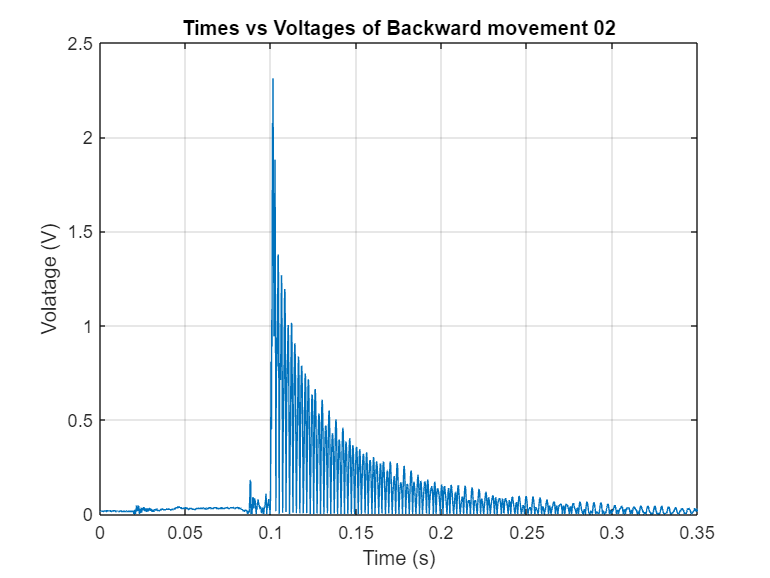


figure()
plot(time_2_b,b_flip_02)
xlim([0 0.35])
title("Times vs Voltages of Backward movement 02")
xlabel("Time (s)")
ylabel("Volatage (V)")
grid on

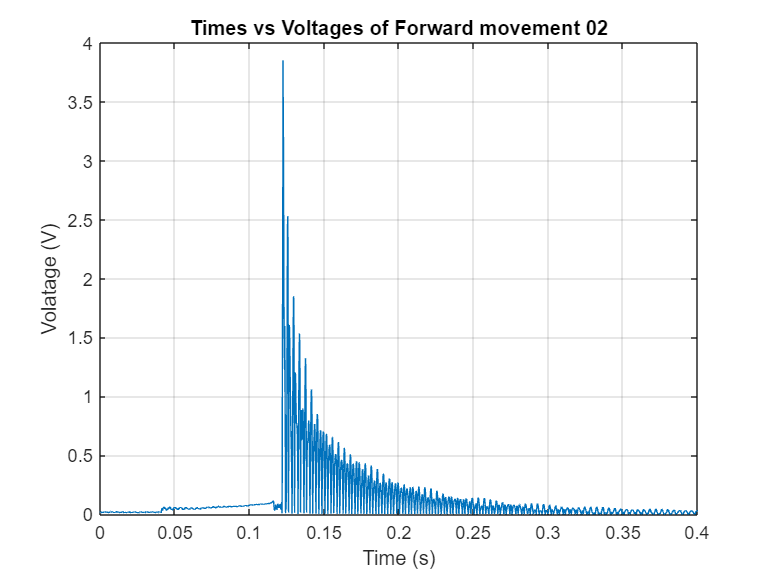


figure()
plot(time_2_f,f_flip_02)
title("Times vs Voltages of Forward movement 02")
xlabel("Time (s)")
ylabel("Volatage (V)")
grid on
xlim([0 0.4])


%ลูกสาม
time_3_b = 0:1e-5:(6.885e+5-6.489e+5)*1e-5;
time_3_f = 0:1e-5:(7.444e+5-7.022e+5)*1e-5;
backing_3 = dataArray(6.489e+5:6.885e+5,2);
forwarding_3 = dataArray(7.022e+5:7.444e+5,2);
b_flip_03 = abs(backing_3)

b_flip_03 =     0.0145
    0.0182
    0.0145
    0.0145
    0.0145
    0.0182
    0.0145
    0.0145
    0.0182
    0.0145


f_flip_03 = abs(forwarding_3)

f_flip_03 =     0.0182
    0.0182
    0.0182
    0.0182
    0.0182
    0.0182
    0.0182
    0.0182
    0.0145
    0.0182



b_power_03 = b_flip_03.^2/R

b_power_03 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


f_power_03 = f_flip_03.^2/R

f_power_03 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


en_b03 = 0

en_b03 = 0

en_f03 = 0

en_f03 = 0

for j=1:length(b_power_03)-1
    en_b03 = en_b03 + (b_power_03(j+1)+b_power_03(j))*(time_3_b(j+1)-time_3_b(j))/2;
end
for j=1:length(f_power_03)-1
    en_f03 = en_f03 + (f_power_03(j+1)+f_power_03(j))*(time_3_f(j+1)-time_3_f(j))/2;
end
en_b03

en_b03 = 1.0140e-05

en_f03

en_f03 = 3.0821e-05

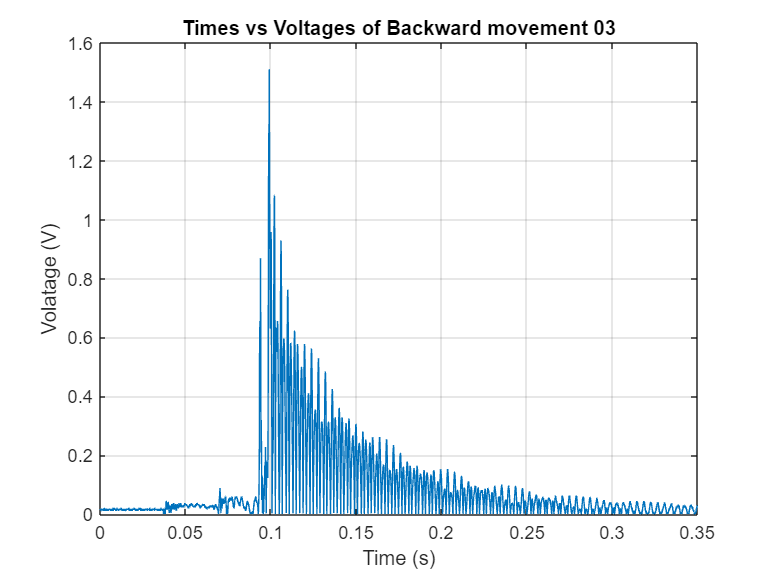



figure()
plot(time_3_b,b_flip_03)
xlim([0 0.35])
title("Times vs Voltages of Backward movement 03")
xlabel("Time (s)")
ylabel("Volatage (V)")
grid on

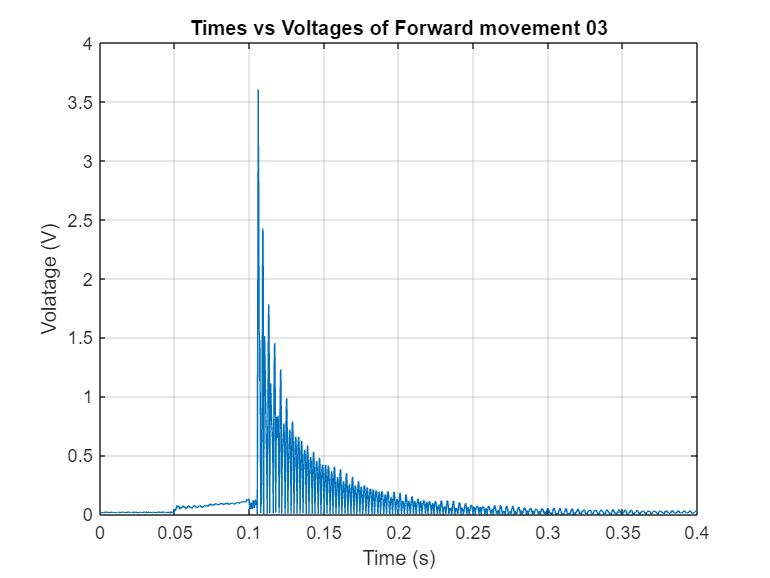


figure()
plot(time_3_f,f_flip_03)
title("Times vs Voltages of Forward movement 03")
xlabel("Time (s)")
ylabel("Volatage (V)")
xlim([0 0.4])
grid on